clear all

file = 'RG_ArgoClim_Salinity_2019.nc';
ncid = netcdf.open(file);
A_number = netcdf.getVar(ncid,3);

meta = ncinfo('RG_ArgoClim_Salinity_2019.nc');
disp('Variable List');

Variable List


disp({meta.Variables.Name}')

    {'LONGITUDE'            }
    {'LATITUDE'             }
    {'PRESSURE'             }
    {'TIME'                 }
    {'ARGO_SALINITY_MEAN'   }
    {'ARGO_SALINITY_ANOMALY'}
    {'BATHYMETRY_MASK'      }
    {'MAPPING_MASK'         }



salinity_a = ncread(file,'ARGO_SALINITY_ANOMALY');
size(salinity_a)

ans =    360   145    58   180


lon = ncread(file,'LONGITUDE');
lat = ncread(file,'LATITUDE');
t =  ncread(file,'TIME');
tmon = datenum(2004,1+(0:length(t)-1)',15);
pressure = ncread(file,'PRESSURE');

k = find(pressure < 100);
pressure(k);
salinity_100_a = mean(salinity_a(:,:,k),3);

size(salinity_a);
%Longitude-360,Latitude-145,Pressure-58,Time (Months)-180
size(salinity_100_a);
%Longitude-360,Latitude-145

salinity_a(111,65,:,:);
salinity_a(261,65,:,:);

lon(133);   %152.5
lon(279);   %298.5

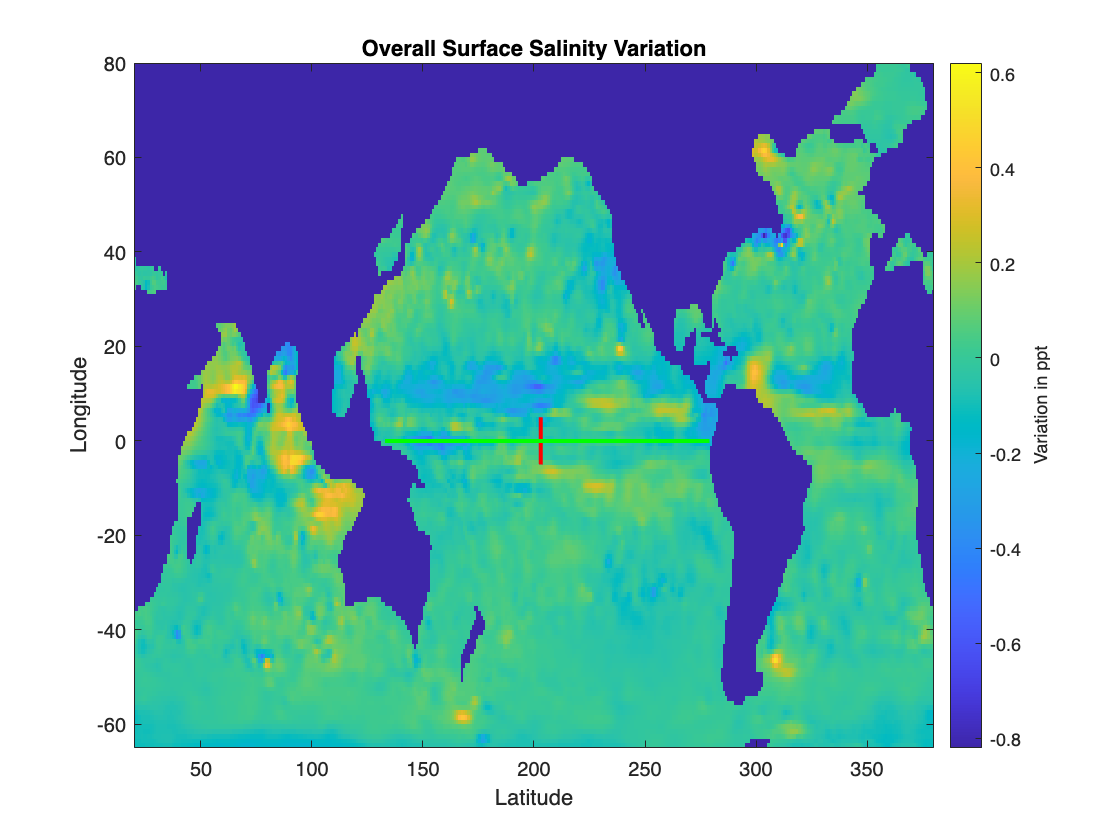

imagesc(lon,lat,squeeze(salinity_100_a(:,:,end))')
set(gca,'ydir','normal')
%Area of Concern: Latitude  -5N to 5N, Longitude 152.5 to  298.5
line([203,203],[-5,5],'Color','r','LineWidth',2)
line([133,279],[0,0],'Color','g','LineWidth',2)
xlabel('Latitude')
ylabel('Longitude')
title('Overall Surface Salinity Variation')
cb = colorbar;
ylabel(cb,'Variation in ppt')

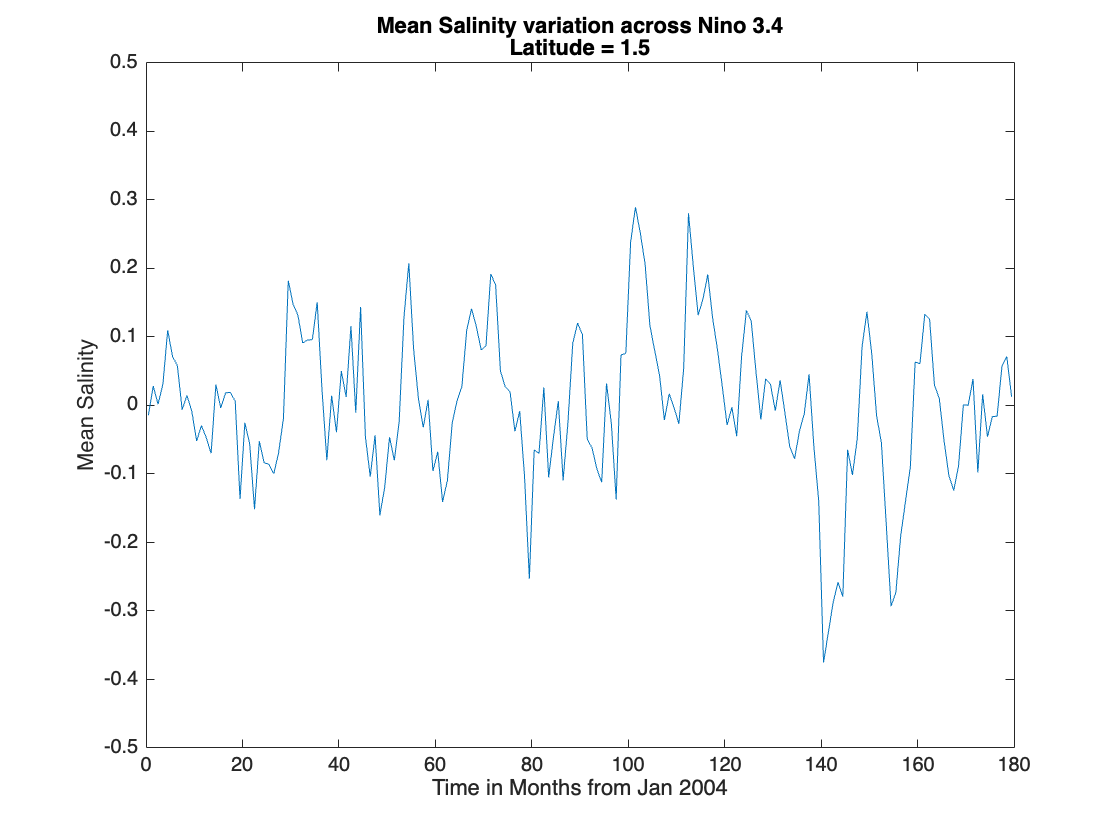

for j = 1:10
    salinity_Nino = mean(salinity_a(203,71-j,k,:),3);
    plot(t,squeeze(salinity_Nino))
    title({'Mean Salinity variation across Nino 3.4',['Latitude = ',num2str(5.5-j)]})
    ylim([-0.5 0.5])
    xlabel('Time in Months from Jan 2004');
    ylabel('Mean Salinity');
    pause (1.5)
end

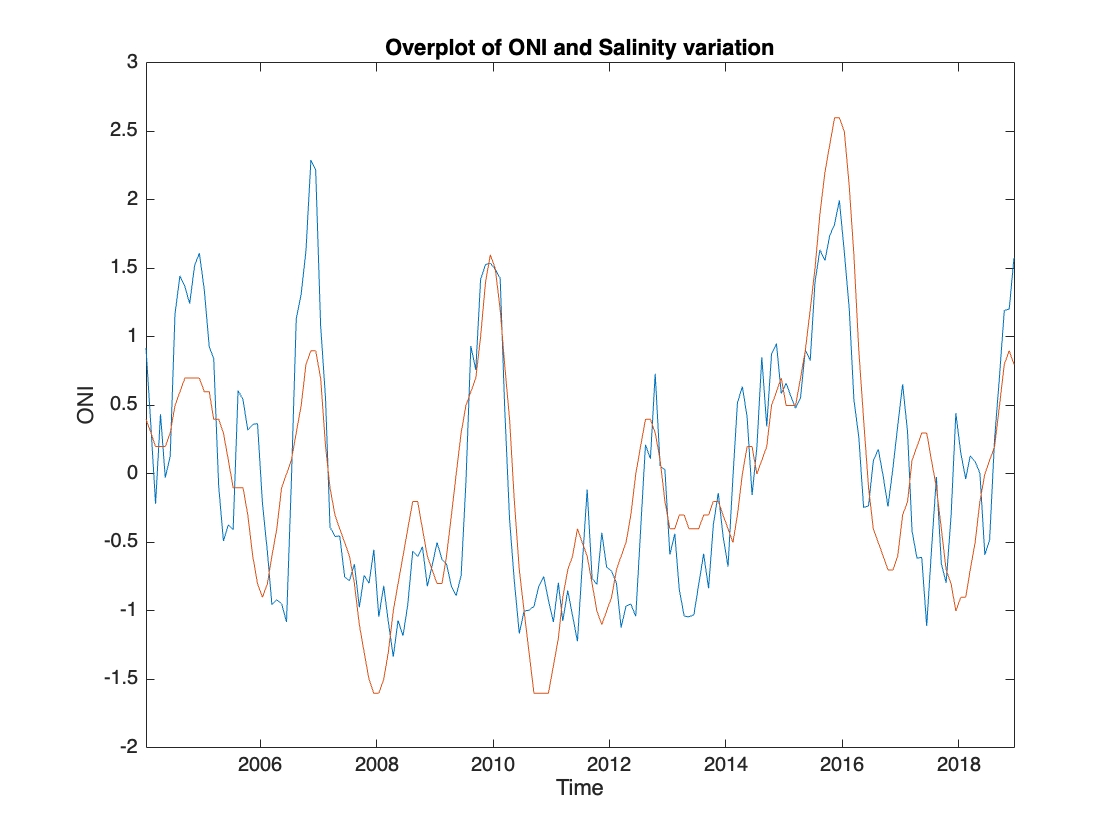

for j = 1:30
    salinity_Nino = mean(salinity_a(223-j,71,k,:),3);
    plot(t,squeeze(salinity_Nino))
    title({'Mean Salinity variation along Nino 3.4',['Longitude = ',num2str(242.5-j)]})
    title(['Longitude = ',num2str(223-j)])
    ylim([-0.6 0.6])
    xlabel('Time in Months from Jan 2004');
    ylabel('Mean Salinity');
    pause (0.7)
end

pavg_salinity_Nino = squeeze(mean(salinity_a(:,:,k,:),3));
salinity_grid_Nino = squeeze(mean(pavg_salinity_Nino,3));
k_ocean = find(~isnan(salinity_grid_Nino));
nk = length(k_ocean);
D = NaN(nk,length(t));

T_Lon_P_t = squeeze(salinity_a(112:260,65,:,:));
[mlon,mp,mt] = size(T_Lon_P_t);
D = NaN(mlon*mp,mt);
for j = 1:mt
    TT = squeeze(T_Lon_P_t(:,:,j));
    D(:,j) = TT(:);
end

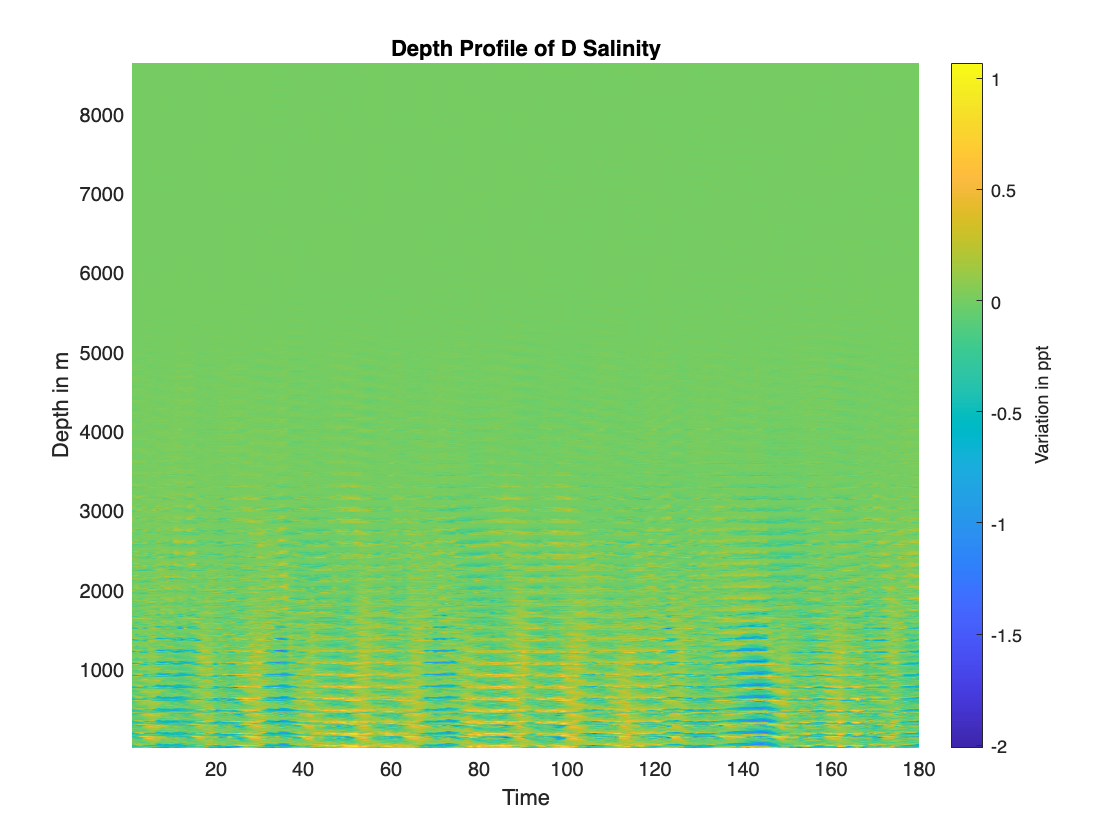

pcolor(D)
shading interp
title('Depth Profile of D Salinity')
ylabel('Depth in m')
cb = colorbar;
ylabel(cb,'Variation in ppt')
xlabel('Time')

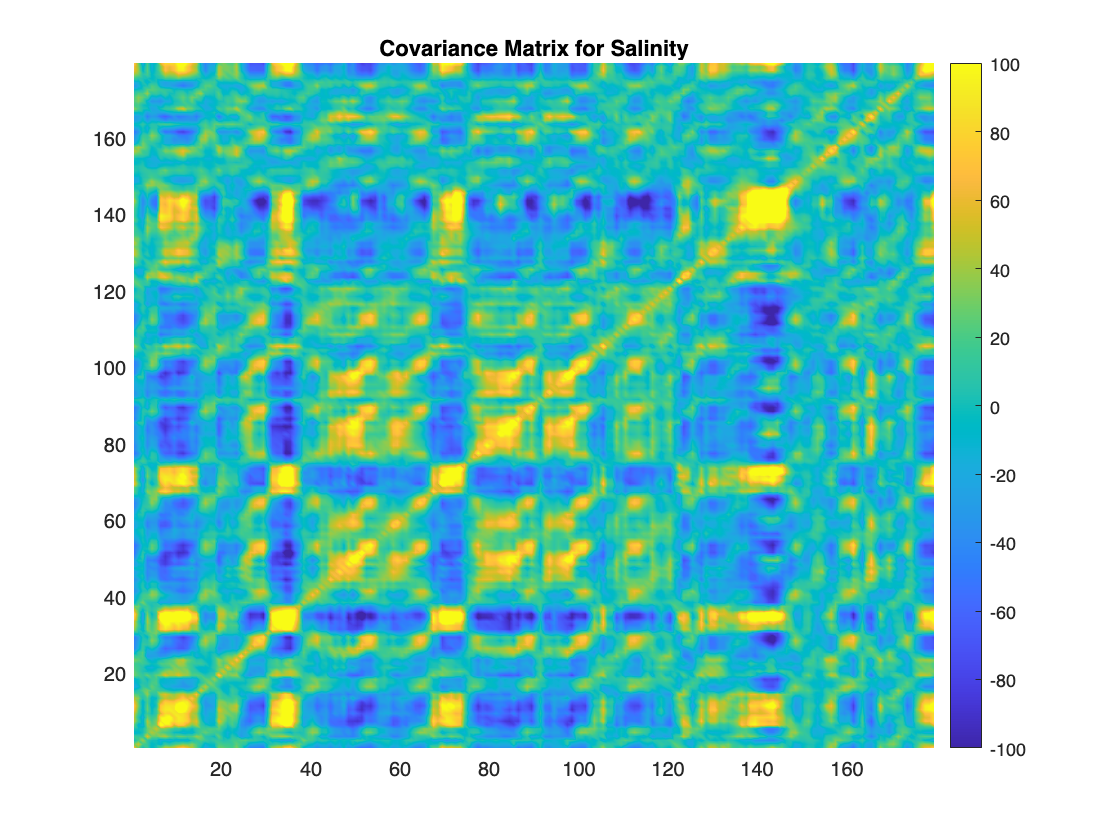

C = D'*D;
figure (1)
pcolor(t,t,C)
shading interp
colorbar
caxis([-1e2 1e2])
title('Covariance Matrix for Salinity')

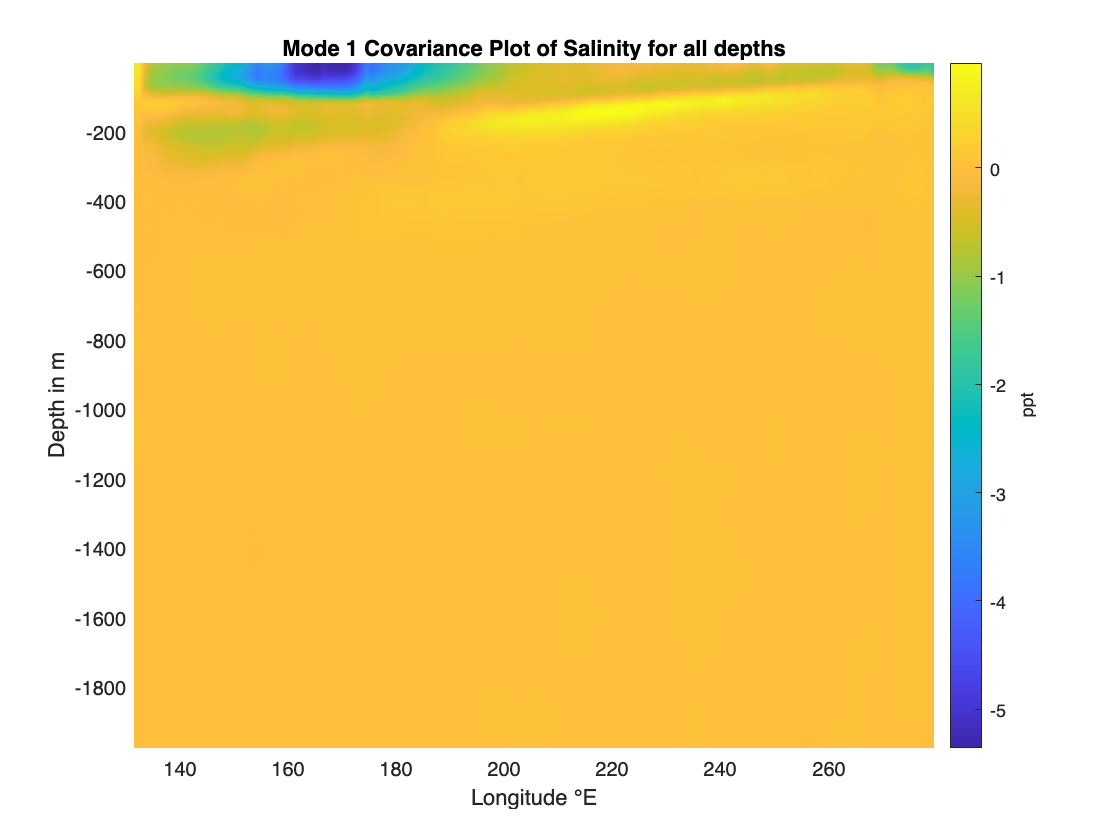

[e,lambda] = eig(C);        %e = eigenvectors, lambda = eigenvalues
lambda = diag(lambda);
if(lambda(1) < lambda(end))
    lambda = fliplr(lambda(:)');
    e = fliplr(e);
end
a = D*e; 

m1 = NaN(149,58);
m1 = reshape(a(:,1),149,58);
pcolor(lon(112:260),-pressure,m1')
shading interp
cb = colorbar;
ylabel(cb,'ppt')
title('Mode 1 Covariance Plot of Salinity for all depths')
ylabel('Depth in m')
xlabel('Longitude °E')

%Rain signal in Eastern Pacific
%Salinity decreases due to rainfall

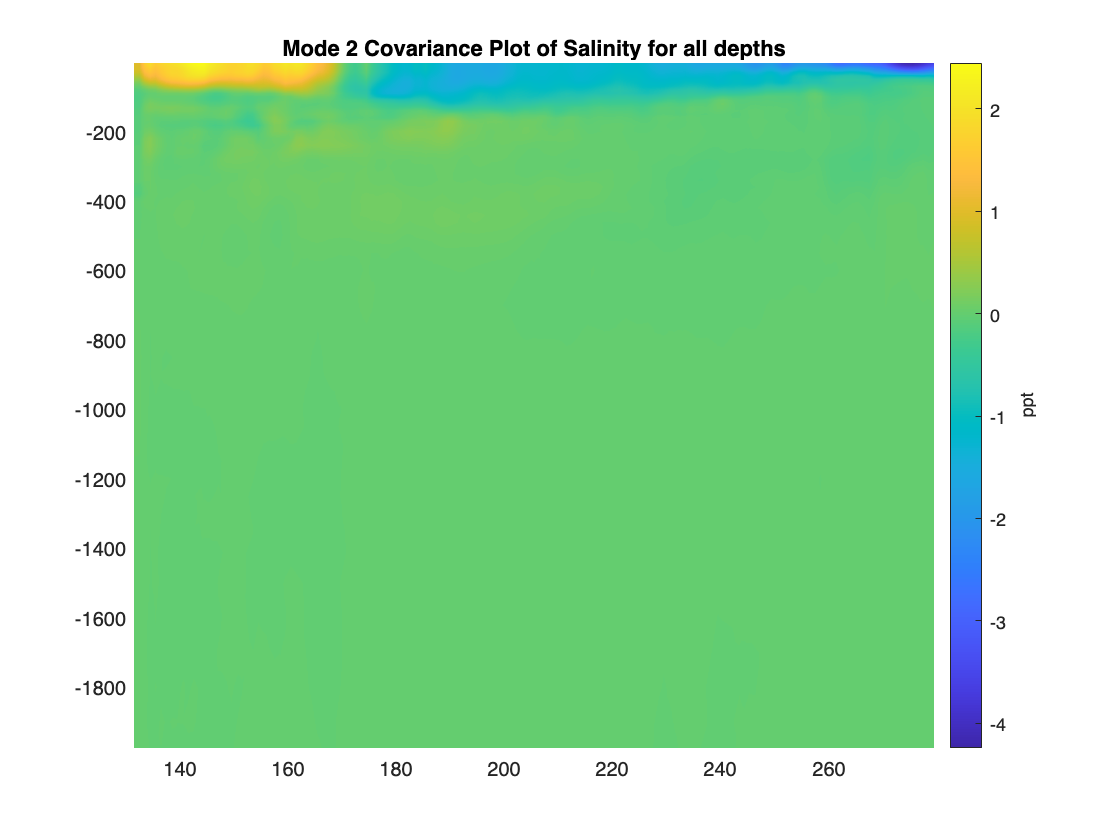

m2 = NaN(149,58);
m2 = reshape(a(:,2),149,58);
pcolor(lon(112:260),-pressure,m2')
shading interp
cb = colorbar;
ylabel(cb,'ppt')
title('Mode 2 Covariance Plot of Salinity for all depths')

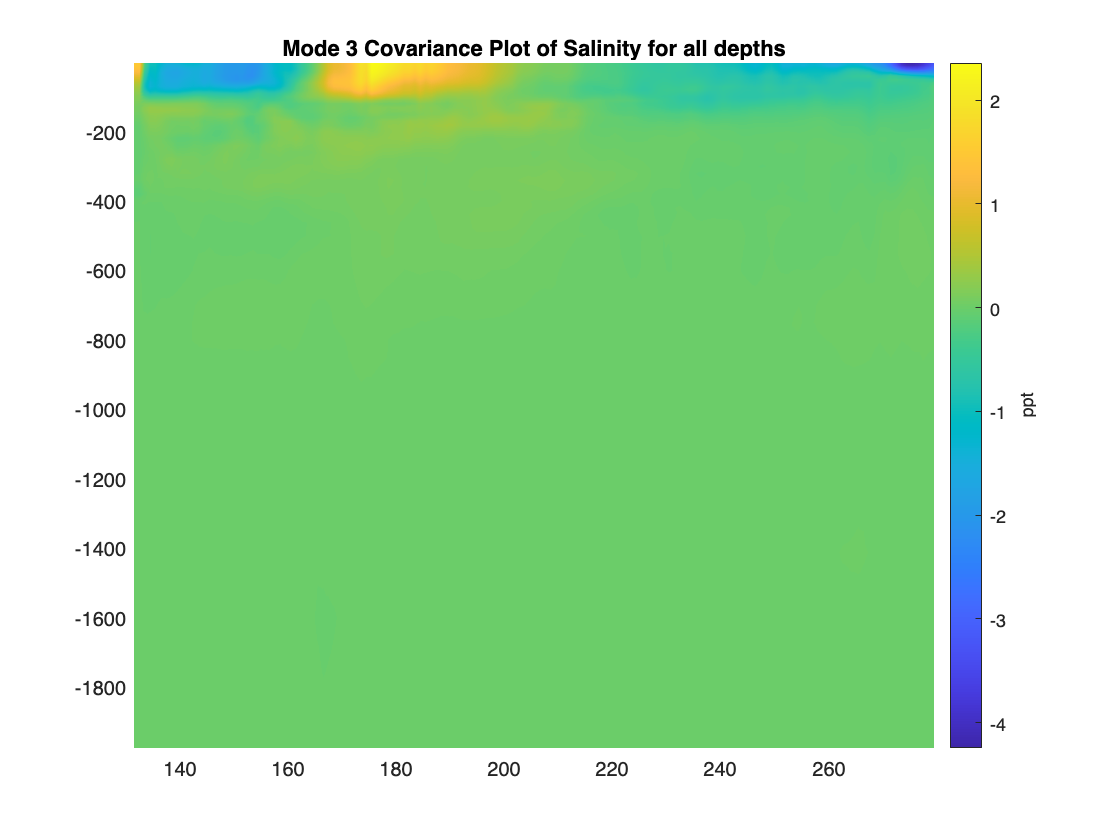

m3 = NaN(149,58);
m3 = reshape(a(:,3),149,58);
pcolor(lon(112:260),-pressure,m3')
shading interp
cb = colorbar;
ylabel(cb,'ppt')
title('Mode 3 Covariance Plot of Salinity for all depths')

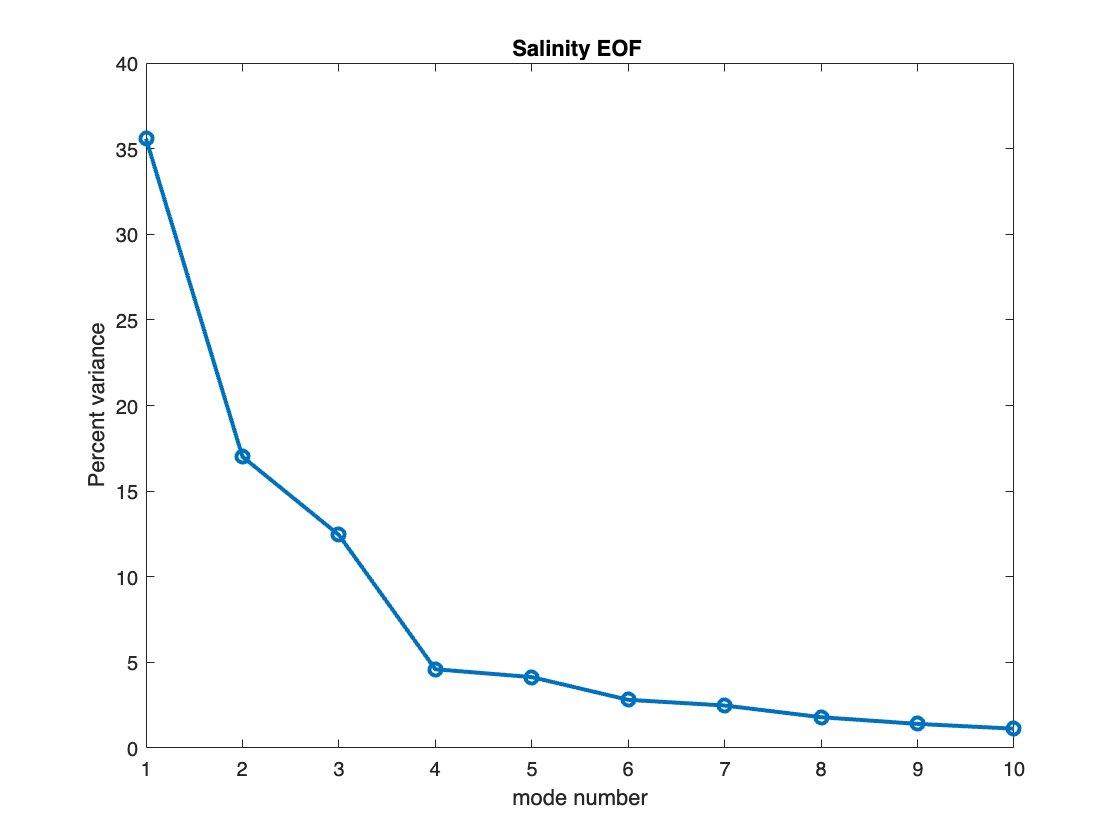

figure (2)
pvar = lambda/sum(lambda)*100;
plot(pvar,'o-','LineWidth',2)
xlim([1,10])
ylabel('Percent variance')
xlabel('mode number')
title('Salinity EOF ')

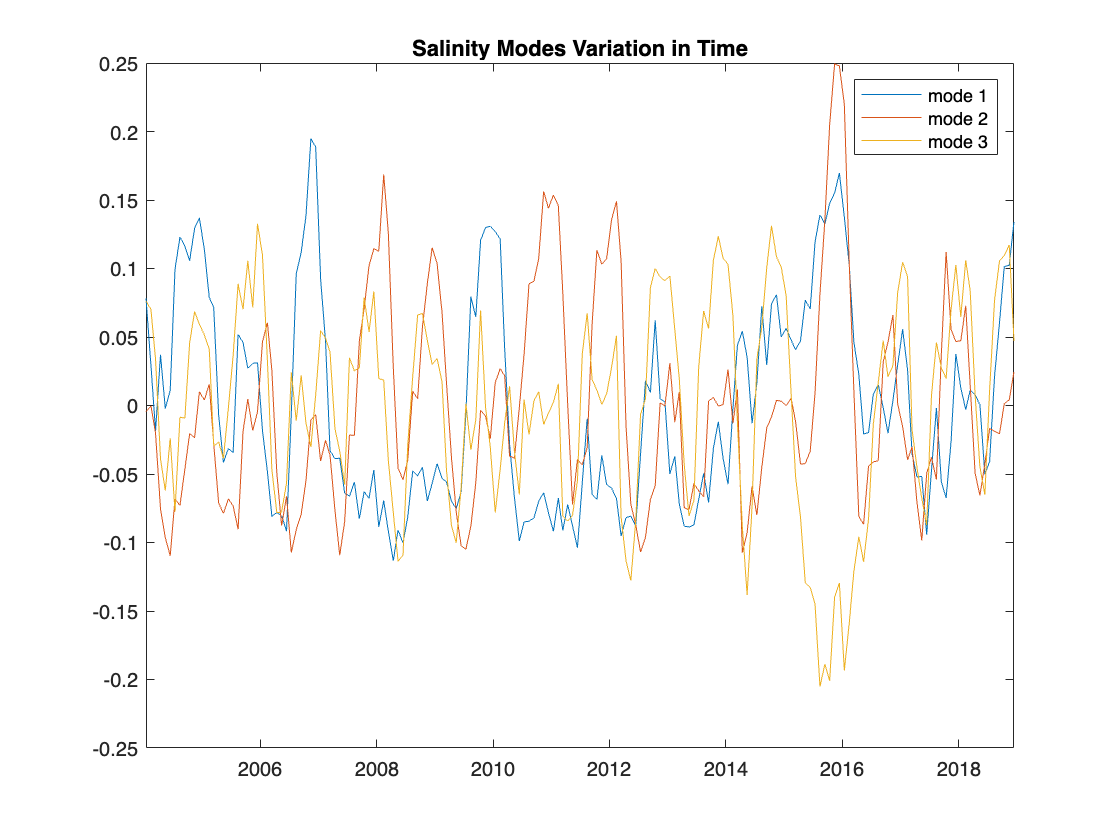

figure (3)
t_data =datetime(tmon,'ConvertFrom', 'datenum', 'Format', 'dd-MM-yy');
plot(t_data,e(:,1:3))
title('Salinity Modes Variation in Time')
legend('mode 1','mode 2','mode 3')

load oni_index.mat

% t1 = datetime(2004,1,15,8,0,0);
% t2 = datetime(2018,12,15,8,0,0);
% t_init = t1:caldays(30):t2;
%t = datetime(2004,1,15) + calmonths(0:179);
tmon;
t_data =datetime(tmon,'ConvertFrom', 'datenum', 'Format', 'dd-MM-yy');
t_nino = datetime(oni_datenum,'ConvertFrom', 'datenum', 'Format', 'dd-MM-yy');
t_nino(648)

ans = datetime
   15-12-03


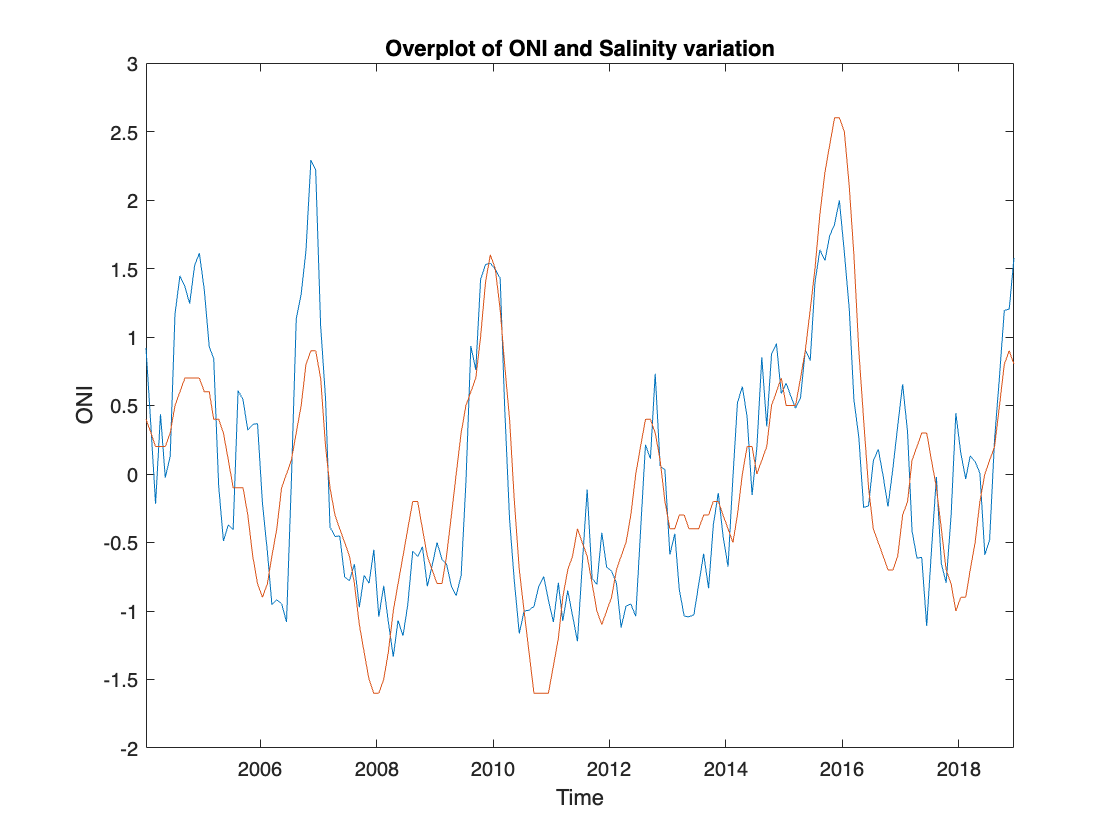

figure(4)
clf
%[yr,mo,dy] = datevec(t);
plot(t_data,e(:,1)/0.085)
hold on
plot(t_nino(649:828),oni_index(649:828))
hold off
title('Overplot of ONI and Salinity variation')
xlabel('Time')
ylabel('ONI')

The correlation of Mode 1 with ONI

corr(oni_index(649:828),e(:,1))

ans = 0.7799